# Homework 2: One-layer perceptron


$$\underline{x}^{(\mu)}=[x_1^{(\mu)}, x_2^{(\mu)}]^T$$



$$t^{\mu}=\pm1$$


Start by normalizing the data by centering each of the two input components and normalizing their respective variances to 1.

Your task is to train a perceptron with one fully-connected hidden layer, two input terminals and one output unit. Use the following network layout:

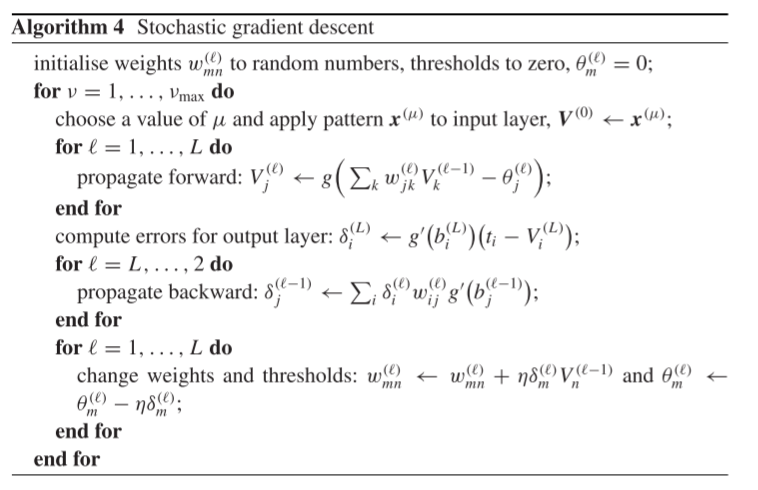

clc
clear
syms x
training_set = readmatrix("training_set.csv");
validation_set = readmatrix("validation_set.csv");
g = tanh(x);
eta = 0.05;
N = 2;
epoch_n = 6;

## Preprocessing

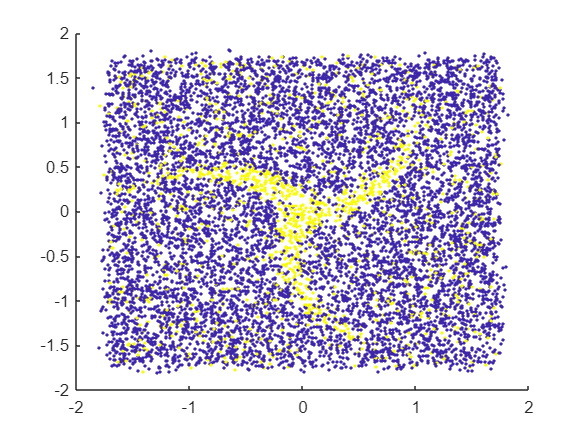

train_input_raw = training_set(:,1:2);
train_input = normalize(train_input_raw)';      % [2x10000]
target = training_set(:,3);                     % [10000x1]
scatter(train_input(1,:),train_input(2,:),[],target,'.')

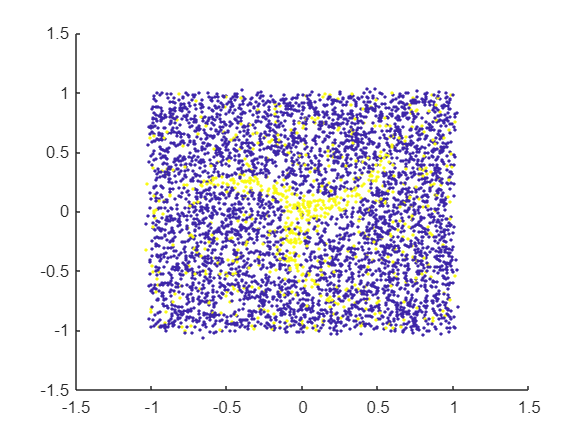


p = size(train_input,2);

validation_input = validation_set(:,1:2)';      % [2x5000]
validation_target = validation_set(:,3);        % [5000x1]
scatter(validation_input(1,:),validation_input(2,:),[],validation_target,'.')

p_val = size(validation_input,2);

## Initialization

Different number of hidden neurons in the hidden layer.

M = 4; 
w = normrnd(0, 1/M, [M,2]);     % [Mx2] w_jk
theta = zeros([M,1]);           % [Mx1] theta_j
W = normrnd(0, 1/M, [1, M]);    % [1xM] W_ij i=1
Theta = 0;
V = zeros([M,1]);               % [Mx1] V_j
Out = 0;
H_train = [];
H_val = [];

## Set energy function

## Training

for ep=1:epoch_n
    for nu = 1 : p
        mu = randi([1,p]);
        x_mu = train_input(:,mu); % randomly pick an input from training set
        t_mu = target(mu);
    
        % propagate forward
        b_mu = w*x_mu-theta;    % [3x1]
        V = tanh(b_mu);         % activation function g = tanh()
        B_mu = W*V-Theta;  % scalar
        Out = tanh(B_mu);       % scalar
        % end of propagate forward
    
        % back propagation
        %% update W
        B = B_mu;
        t = target(mu);
        g_prime_B = eval(subs(diff(g), B));
        Delta = (t - Out) * g_prime_B;
        delta_W = eta * Delta * V';
        W = W + delta_W;
        
        %% update w
        % assume m=1
        delta_w = zeros(size(w));
        delta_theta = zeros(size(theta));
        for n = 1:N
            x_n = x_mu(n);
            for m = 1:M
                b_m = b_mu(m);
                g_prime_b_m = eval(subs(diff(g), b_m));
                delta_m = Delta * W(1,m) * g_prime_b_m;
                delta_theta(m) = -eta * delta_m;
                delta_w(m,n) = -eta * delta_m * x_n;
            end
        end
        w = w + delta_w;
        
        %% update Theta
        delta_Theta = -eta * Delta;
        Theta = Theta + delta_Theta;
    
        %% update theta
        theta = theta + delta_theta; 
        % end of back propagation
    end
    H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
    H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);
end

## Validation

tmp = 0;
for mu = 1:p_val
    x_mu = validation_input(:,mu);
    b_mu = w * x_mu - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
    tmp = tmp + abs(validation_target(mu)-sign(Out));
end
C = 1/(2*p_val)*tmp

C = 0.1516

## Plot H

figure
hold on
plot(1:epoch_n,log(H_train))
plot(1:epoch_n,log(H_val))
legend('H\_train','H\_val')
hold off

Out = -0.1859

Out2 = -0.1859

function Out = fd_prop(W, w, Theta, theta, x)
    b_mu = w * x - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
end

function H = energy(W, w, Theta, theta, input_set, target_set)
    H = 0;
    for mu = 1:size(input_set, 2)
        Out = fd_prop(W,w,Theta,theta,input_set(:,mu));
        H = H + (target_set(mu)-Out)^2;
    end
    H = H * 0.5;
end